Tutorial02 2.3 Fitting the model, Assignment.

Pre-processing.

load g149novickA.mat
who  % to check what variables are loaded


Your variables are:

A            V2           V_fit        b            tau          tau3         time         y_data       
V            V3           a            data         tau1         tau4         x_dataB      y_dataB      
V1           V4           ans          data_less10  tau2         tau_fit      x_time       




%data  % see what's in "data"
x_time = data(:,1); % extract the 1st col of data
y_data = data(:,2); % extract the 2nd col of data

a) 

Note: **superimpose** = lay one thing over another.

time = 0:0.1:10;
tau1 = 1;
tau2 = 2;
tau3 = 5;
tau4 = 10;



V1 = 1-exp(-time/tau1);
V2 = 1-exp(-time/tau2);
V3 = 1-exp(-time/tau3);
V4 = 1-exp(-time/tau4);

tau_fit = 3.455

tau_fit = 3.4550

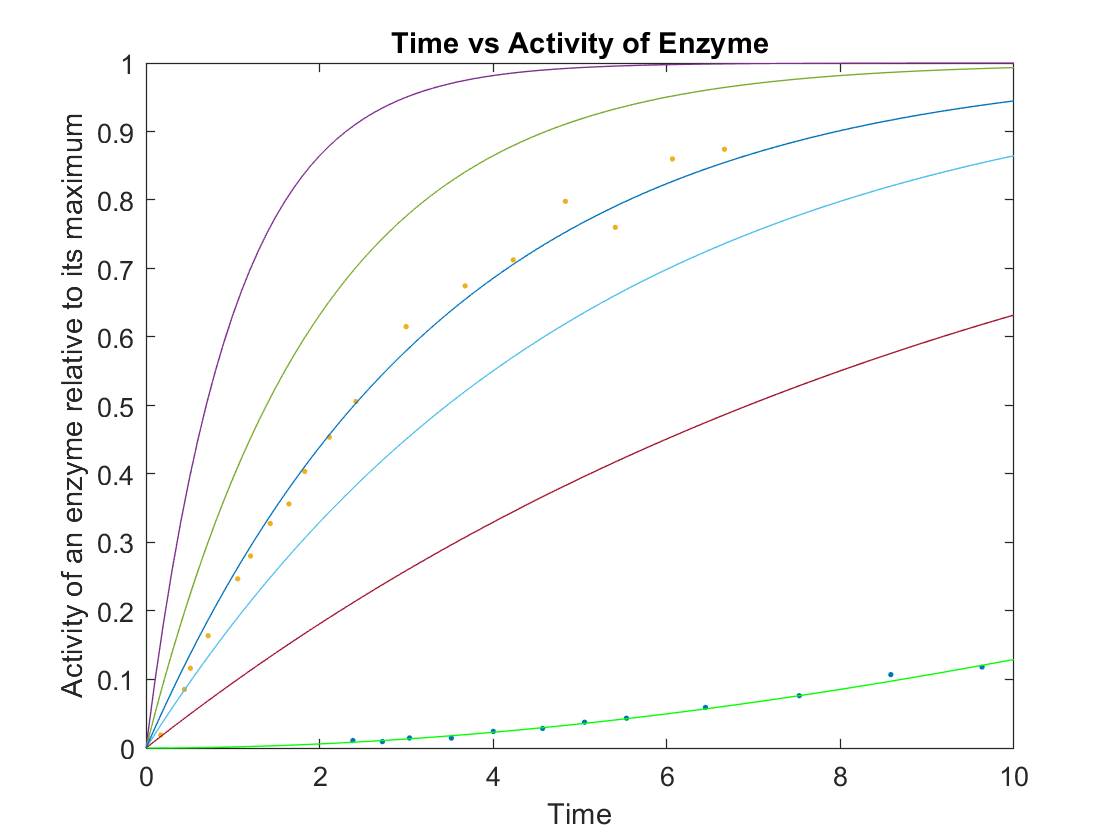

V_fit = 1-exp(-time/tau_fit);

plot(x_time, y_data, ".")
hold on
plot(time, V1)
plot(time, V2)
plot(time, V3)
plot(time, V4)
plot(time, V_fit)
hold off

title('Time vs Activity of Enzyme')
xlabel('Time')
ylabel('Activity of an enzyme relative to its maximum')

**Conclusion**: tau = 3.455 seems to give a curve that fit the data points.

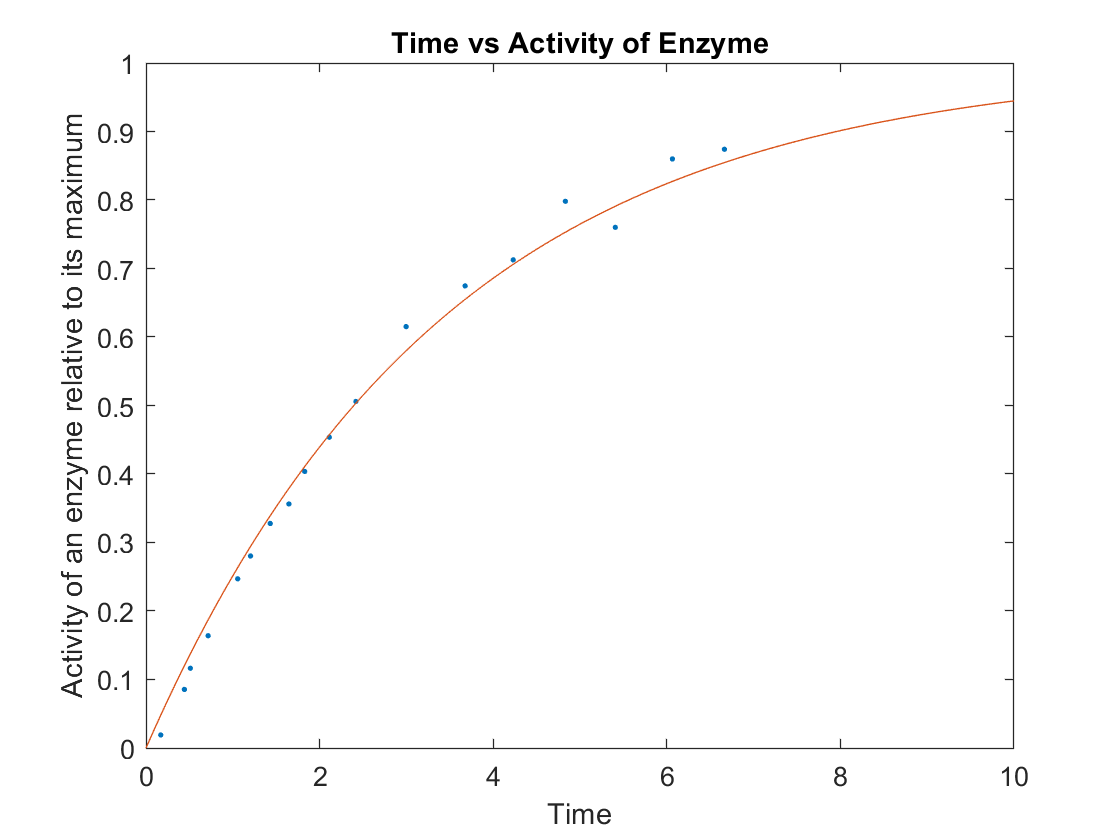

plot(x_time, y_data, ".")
hold on
plot(time, V_fit)
hold off
title('Time vs Activity of Enzyme')
xlabel('Time')
ylabel('Activity of an enzyme relative to its maximum')

b) Try the same thing for **g149novickB.mat**

load g149novickB.mat
who


Your variables are:

A            V2           V_fit        b            tau          tau3         time         y_data       
V            V3           a            data         tau1         tau4         x_dataB      y_dataB      
V1           V4           ans          data_less10  tau2         tau_fit      x_time       



data

data =     2.3832    0.0109
    2.7230    0.0093
    3.0358    0.0146
    3.5177    0.0145
    4.0014    0.0242
    4.5692    0.0286
    5.0528    0.0376
    5.5358    0.0435
    6.4458    0.0592
    7.5262    0.0764



% Extract data where time < 10 hours
data_less10 = data(data(:,1)<10, :)

data_less10 =     2.3832    0.0109
    2.7230    0.0093
    3.0358    0.0146
    3.5177    0.0145
    4.0014    0.0242
    4.5692    0.0286
    5.0528    0.0376
    5.5358    0.0435
    6.4458    0.0592
    7.5262    0.0764


% Personally an IMPT line ^
x_dataB = data_less10(:,1)  % extract 1st col = time

x_dataB =     2.3832
    2.7230
    3.0358
    3.5177
    4.0014
    4.5692
    5.0528
    5.5358
    6.4458
    7.5262


y_dataB = data_less10(:,2)  % extract 2nd col = measurements

y_dataB =     0.0109
    0.0093
    0.0146
    0.0145
    0.0242
    0.0286
    0.0376
    0.0435
    0.0592
    0.0764


Try to fit the remaining data to the family of fns in Eqn(2).

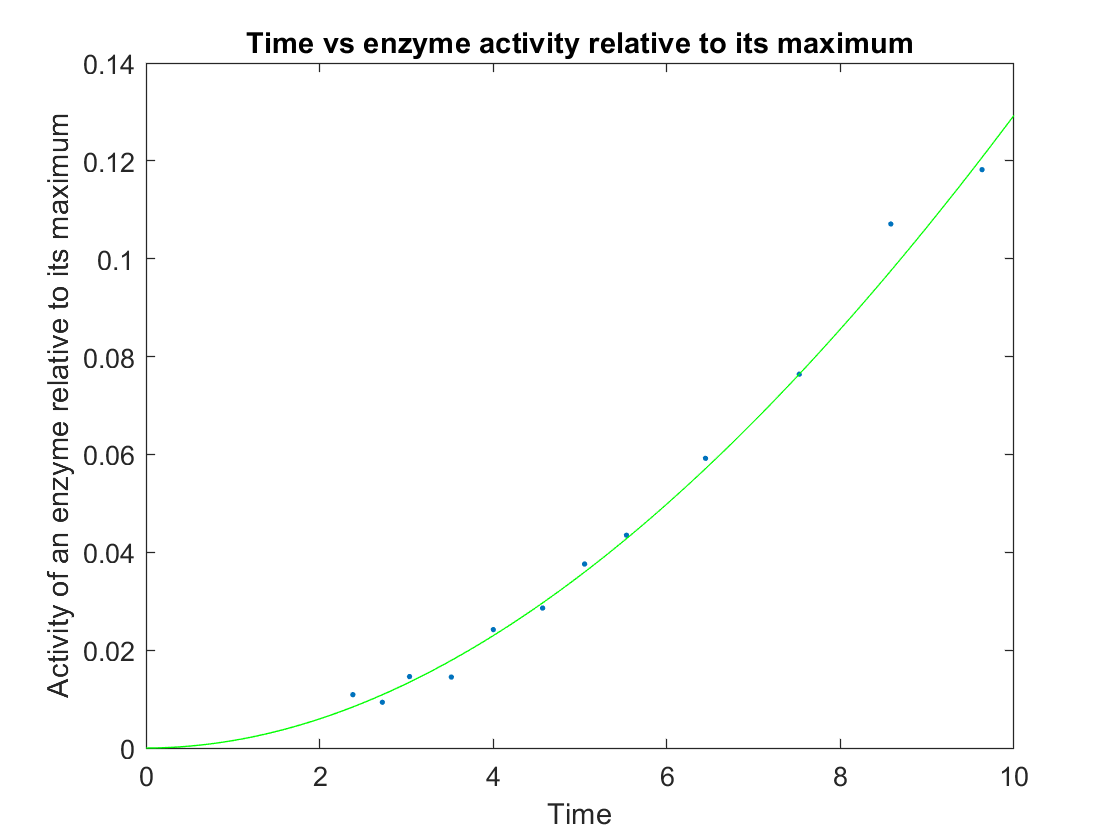

time = 0:0.1:10;
tau = 18;
A = 1;

V = A*(exp(-time/tau) - 1 + time/tau);

plot(x_dataB, y_dataB, '.')
hold on
plot(time, V, 'green')
title('Time vs enzyme activity relative to its maximum')
xlabel('Time')
ylabel('Activity of an enzyme relative to its maximum')

**Conclusion**: tau = 18 seems to give a curve that fit the curve.